% jan 2016

% EXERCISE 2

## RP PLANAR ROBOT

syms q1 real
syms q2 real

alpha = [pi/2 0];
a=[0 0];
d=[0 q2];
theta=[q1 0];

table=[alpha',a',d',theta']

$$table = \left(\begin{array}{cccc} \frac{\pi }{2} & 0 & 0 & q_{1}\\ 0 & 0 & q_{2} & 0 \end{array}\right)$$

%plot the robot

%Note: it has different format respect to Sveva's DHMatrix function

a_no_sym = a%double(subs(a, {l1,l2,l3}, {l_1,l_2,l_3}));

a_no_sym =      0     0


alpha_no_sym = alpha;
d_no_sym = double(subs(d,{q2},{0}));
theta_no_sym = double(subs(theta, {q1}, {0}));

DHTable=[a_no_sym', alpha_no_sym',d_no_sym',theta_no_sym']

DHTable =          0    1.5708         0         0
         0         0         0         0


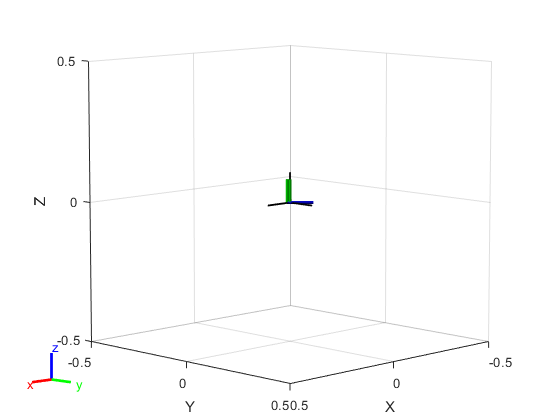

joints = 'RP';
robot_model = build_robot_model(joints, DHTable);

%config = homeConfiguration(robot_model)%build_configuration(robot_model, array_joint_values);

show(robot_model, randomConfiguration(robot_model));%config);

% KINEMATIC
fprintf("______________________________Direct Kinematic___________________________________\n")

______________________________Direct Kinematic___________________________________


[T, A] = DHMatrix(table);
A0_1=A{1};
A1_2=A{2};
T;
% how to obtain f_r, (i.e. r)
%{
    From DH table:
        A0_2 = A0_1 * A1_2 //mapping from frame 2 to frame 0
    So, to obtain the origin of frame 2 in frame 0:
        O2_2 = [0 0 0] % 3D space
            -> O2_2_H = [0 0 0 1] //homog. transf
        
        r = O0_2 = [rx ry rz 1]' = A0_2*O2_2_H 
%}
f_r_3D = get_f_r(T); %(X Y Z PHI)

f_r = [f_r_3D(1); f_r_3D(2)]

$$f\_r = \left(\begin{array}{c} q_{2}\,\sin\left(q_{1}\right)\\ -q_{2}\,\cos\left(q_{1}\right) \end{array}\right)$$

fprintf("______________________________Inverse Kinematic___________________________________\n")

______________________________Inverse Kinematic___________________________________


syms px py

%positive solution
q2_p=sqrt(px^2 + py^2);
q1_p = atan2(px/q2_p, -py/q2_p);
q_p = [q1_p;q2_p]

$$q\_p = \left(\begin{array}{c} \text{atan2}\left(\frac{\mathrm{px}}{\sqrt{{\mathrm{px}}^{2}+{\mathrm{py}}^{2}}},-\frac{\mathrm{py}}{\sqrt{{\mathrm{px}}^{2}+{\mathrm{py}}^{2}}}\right)\\ \sqrt{{\mathrm{px}}^{2}+{\mathrm{py}}^{2}} \end{array}\right)$$

    
%negative solution
q2_n = -sqrt(px^2 + py^2);
q1_n = atan2(px/q2_n, -py/q2_n);
q_n = [q1_n;q2_n]

$$q\_n = \left(\begin{array}{c} \text{atan2}\left(-\frac{\mathrm{px}}{\sqrt{{\mathrm{px}}^{2}+{\mathrm{py}}^{2}}},\frac{\mathrm{py}}{\sqrt{{\mathrm{px}}^{2}+{\mathrm{py}}^{2}}}\right)\\ -\sqrt{{\mathrm{px}}^{2}+{\mathrm{py}}^{2}} \end{array}\right)$$

px = -1

px = -1

py = 1

py = 1


q0_p = subs(q_p)

$$q0\_p = \left(\begin{array}{c} -\frac{3\,\pi }{4}\\ \sqrt{2} \end{array}\right)$$

    double(q0_p)

ans =    -2.3562
    1.4142



q0_n = subs(q_n)

$$q0\_n = \left(\begin{array}{c} \frac{\pi }{4}\\ -\sqrt{2} \end{array}\right)$$

    double(q0_n)

ans =     0.7854
   -1.4142


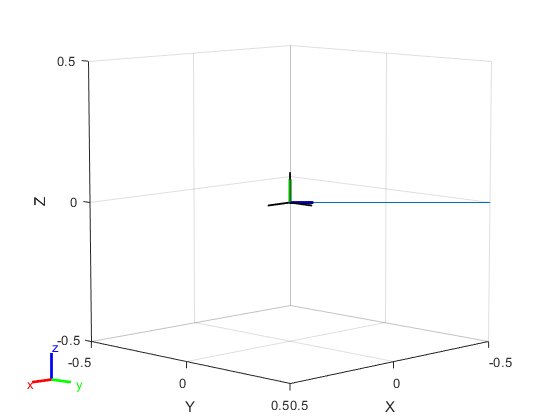

config = build_configuration(robot_model, double(q0_p));
show(robot_model, config);

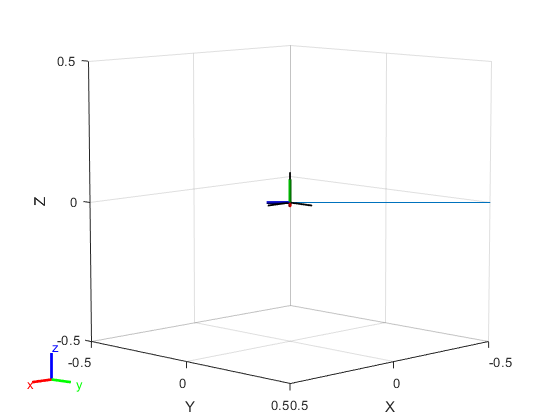

config = build_configuration(robot_model, double(q0_n));
show(robot_model, config);

% DINAMIC
fprintf("______________________________Diff___________________________________\n")

______________________________Diff___________________________________


J = simplify(jacobian(f_r, [q1 q2]))

$$J = \left(\begin{array}{cc} q_{2}\,\cos\left(q_{1}\right) & \sin\left(q_{1}\right)\\ q_{2}\,\sin\left(q_{1}\right) & -\cos\left(q_{1}\right) \end{array}\right)$$

% EXERCISE 3

## PLANAR 2R (by dh table)

syms q1 real
syms q2 real

syms l1 real
syms l2 real

alpha = [0 0];
a=[l1 l2];
d=[0 0];
theta=[q1 q2];

table=[alpha',a',d',theta']

$$table = \left(\begin{array}{cccc} 0 & l_{1} & 0 & q_{1}\\ 0 & l_{2} & 0 & q_{2} \end{array}\right)$$

%plot the robot

%Note: it has different format respect to Sveva's DHMatrix function
l_1 = 0.1;
l_2 = 0.1;

a_no_sym = double(subs(a, {l1,l2}, {l_1,l_2}));
alpha_no_sym = alpha;
d_no_sym = d;
theta_no_sym = double(subs(theta, {q1,q2}, {0,0}));

DHTable=[a_no_sym', alpha_no_sym',d_no_sym',theta_no_sym']

DHTable =     0.1000         0         0         0
    0.1000         0         0         0


joints = 'RR';
robot_model = build_robot_model(joints, DHTable);

%config = homeConfiguration(robot_model)%build_configuration(robot_model, array_joint_values);

show(robot_model, randomConfiguration(robot_model));%config);

% KINEMATIC
fprintf("______________________________Kinematic___________________________________\n")

______________________________Kinematic___________________________________


[T, A] = DHMatrix(table);
A0_1=A{1};
A1_2=A{2};
T;
f_r_3D = get_f_r(T); %(X Y Z PHI)

f_r = [f_r_3D(1); f_r_3D(2)]

$$f\_r = \left(\begin{array}{c} l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\\ l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right) \end{array}\right)$$

% DINAMIC
fprintf("______________________________Diff___________________________________\n")

______________________________Diff___________________________________


J = simplify(jacobian(f_r, [q1 q2]))

$$J = \left(\begin{array}{cc} -l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right) & -l_{2}\,\sin\left(q_{1}+q_{2}\right)\\ l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right) & l_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

% EXERCISE
l1 = 0.25;
l2=0.25;
J = subs(J)

$$J = \left(\begin{array}{cc} -\frac{\sin\left(q_{1}+q_{2}\right)}{4}-\frac{\sin\left(q_{1}\right)}{4} & -\frac{\sin\left(q_{1}+q_{2}\right)}{4}\\ \frac{\cos\left(q_{1}+q_{2}\right)}{4}+\frac{\cos\left(q_{1}\right)}{4} & \frac{\cos\left(q_{1}+q_{2}\right)}{4} \end{array}\right)$$

q0 = [pi/3 pi/6]

q0 =     1.0472    0.5236


vm = [-0.2 0.1]'

vm =    -0.2000
    0.1000



J_0 = simplify(subs(J, {q1 q2}, {q0(1), q0(2)}))

$$J\_0 = \left(\begin{array}{cc} -\frac{\sqrt{3}}{8}-\frac{1}{4} & -\frac{1}{4}\\ \frac{1}{8} & 0 \end{array}\right)$$

% to obtain qm_dot
% v = J * q_dot
rank_J_0 = rank(J_0)

rank_J_0 = 2

% rank is maximum, so all velocities are feasible, also vm
q_m_dot = linsolve(J_0, vm)

$$q\_m\_dot = \left(\begin{array}{c} \frac{4}{5}\\ -\frac{2\,\sqrt{3}}{5} \end{array}\right)$$

## PLANAR 4R

syms q1 real
syms q2 real
syms q3 real
syms q4 real

syms l1 real
syms l2 real
syms l3 real
syms l4 real

alpha = [0 0 0 0];
a=[l1 l2 l3 l4];
d=[0 0 0 0];
theta=[q1 q2 q3 q4];

table=[alpha',a',d',theta']

$$table = \left(\begin{array}{cccc} 0 & l_{1} & 0 & q_{1}\\ 0 & l_{2} & 0 & q_{2}\\ 0 & l_{3} & 0 & q_{3}\\ 0 & l_{4} & 0 & q_{4} \end{array}\right)$$

%plot the robot

%Note: it has different format respect to Sveva's DHMatrix function
l_1 = 0.1;
l_2 = 0.1;
l_3 = 0.1;
l_4 = 0.1;

a_no_sym = double(subs(a, {l1,l2,l3,l4}, {l_1,l_2,l_3,l_4}));
alpha_no_sym = alpha;
d_no_sym = d;
theta_no_sym = double(subs(theta, {q1,q2,q3,q4}, {0,0,0,0}));

DHTable=[a_no_sym', alpha_no_sym',d_no_sym',theta_no_sym']

DHTable =     0.1000         0         0         0
    0.1000         0         0         0
    0.1000         0         0         0
    0.1000         0         0         0


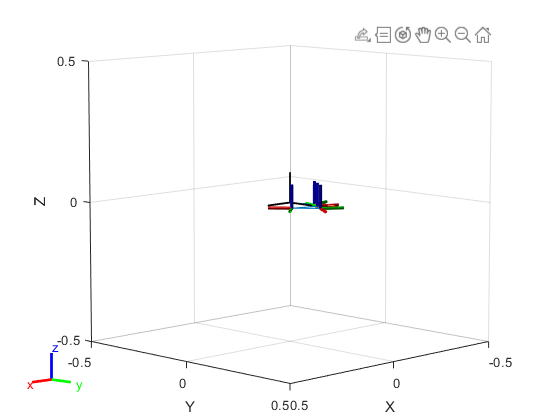

joints = 'RRRR';
robot_model = build_robot_model(joints, DHTable);

%config = homeConfiguration(robot_model)%build_configuration(robot_model, array_joint_values);

show(robot_model, randomConfiguration(robot_model));%config);

% KINEMATIC
fprintf("______________________________Kinematic___________________________________\n")

______________________________Kinematic___________________________________


[T, A] = DHMatrix(table);
A0_1=A{1};
A1_2=A{2};
A2_3=A{3};
A3_4=A{4};

T;
f_r_3D = get_f_r(T); %(X Y Z PHI)

f_r = [f_r_3D(1); f_r_3D(2)]

$$f\_r = \left(\begin{array}{c} l_{4}\,\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right)+l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+l_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right)\\ l_{4}\,\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)+l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)+l_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right) \end{array}\right)$$

% DINAMIC
fprintf("______________________________Diff___________________________________\n")

______________________________Diff___________________________________


J = simplify(jacobian(f_r, [q1 q2 q3 q4]))

$$J = \begin{array}{l} \left(\begin{array}{cccc} -\sigma_{1}-l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right)-\sigma_{3} & -\sigma_{1}-l_{2}\,\sin\left(q_{1}+q_{2}\right)-\sigma_{3} & -\sigma_{1}-\sigma_{3} & -\sigma_{1}\\ \sigma_{2}+l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+\sigma_{4} & \sigma_{2}+l_{2}\,\cos\left(q_{1}+q_{2}\right)+\sigma_{4} & \sigma_{2}+\sigma_{4} & \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{4}\,\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)\\ \sigma_{2}=l_{4}\,\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right)\\ \sigma_{3}=l_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{4}=l_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

% EXERCISE
l1 = 0.25;
l2=0.25;
l3=0.25;
l4=0.25;

J = subs(J)

$$J = \begin{array}{l} \left(\begin{array}{cccc} -\sigma_{3}-\sigma_{1}-\frac{\sin\left(q_{1}+q_{2}\right)}{4}-\frac{\sin\left(q_{1}\right)}{4} & -\sigma_{3}-\sigma_{1}-\frac{\sin\left(q_{1}+q_{2}\right)}{4} & -\sigma_{3}-\sigma_{1} & -\sigma_{1}\\ \sigma_{4}+\sigma_{2}+\frac{\cos\left(q_{1}+q_{2}\right)}{4}+\frac{\cos\left(q_{1}\right)}{4} & \sigma_{4}+\sigma_{2}+\frac{\cos\left(q_{1}+q_{2}\right)}{4} & \sigma_{4}+\sigma_{2} & \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)}{4}\\ \sigma_{2}=\frac{\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right)}{4}\\ \sigma_{3}=\frac{\sin\left(q_{1}+q_{2}+q_{3}\right)}{4}\\ \sigma_{4}=\frac{\cos\left(q_{1}+q_{2}+q_{3}\right)}{4} \end{array}$$

q0 = [pi/3 pi/6 0 -pi/2]

q0 =     1.0472    0.5236         0   -1.5708


ve = [0.2 0]'

ve =     0.2000
         0



J_0 = simplify(subs(J, {q1 q2 q3 q4}, {q0(1), q0(2), q0(3), q0(4)}))

$$J\_0 = \left(\begin{array}{cccc} -\frac{\sqrt{3}}{8}-\frac{1}{2} & -\frac{1}{2} & -\frac{1}{4} & 0\\ \frac{3}{8} & \frac{1}{4} & \frac{1}{4} & \frac{1}{4} \end{array}\right)$$

% to obtain qe_dot
% v = J * q_dot
rank_J_0 = rank(J_0)

rank_J_0 = 2

% rank is maximum, so all velocities are feasible, also ve
% since J_0 is not a squared matrix, we have multiple solution to generate
% ve, but we need to choose only ones that generate also vm

% to realize both vm and ve, we fix [q1_dot, q2_dot] = qm_dot
q1_dot_0 = q_m_dot(1);
q2_dot_0 = q_m_dot(2);
J_0(:,1:2)

$$ans = \left(\begin{array}{cc} -\frac{\sqrt{3}}{8}-\frac{1}{2} & -\frac{1}{2}\\ \frac{3}{8} & \frac{1}{4} \end{array}\right)$$

A = J_0(:,3:end)

$$A = \left(\begin{array}{cc} -\frac{1}{4} & 0\\ \frac{1}{4} & \frac{1}{4} \end{array}\right)$$

b = ve - J_0(:,1:2)*q_m_dot %q1_dot and q2_dot fixed

$$b = \left(\begin{array}{c} \frac{3}{5}-\frac{\sqrt{3}}{10}\\ \frac{\sqrt{3}}{10}-\frac{3}{10} \end{array}\right)$$

sol = linsolve(A,b);
q3_dot_0 = sol(1);
q4_dot_0 = sol(2);
q_dot_0 = [q1_dot_0 q2_dot_0 q3_dot_0 q4_dot_0]'

$$q\_dot\_0 = \left(\begin{array}{c} \frac{4}{5}\\ -\frac{2\,\sqrt{3}}{5}\\ \frac{2\,\sqrt{3}}{5}-\frac{12}{5}\\ \frac{6}{5} \end{array}\right)$$

double(q_dot_0)

ans =     0.8000
   -0.6928
   -1.7072
    1.2000


%check
v = J_0 * q_dot_0

$$v = \left(\begin{array}{c} \frac{1}{5}\\ 0 \end{array}\right)$$